# CNN

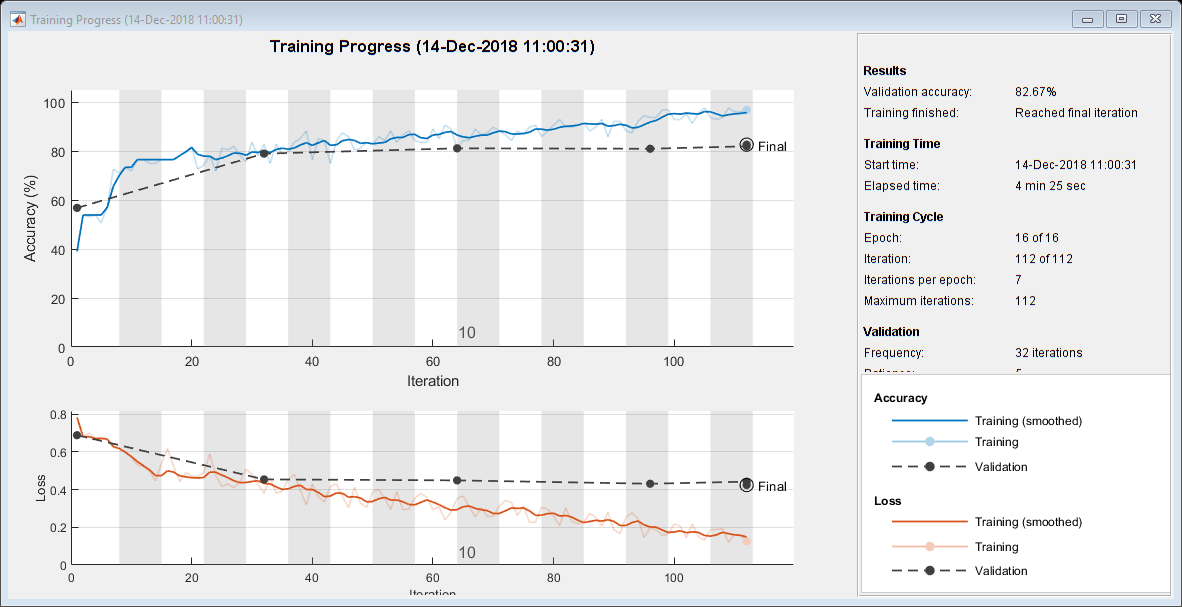

net =   SeriesNetwork with properties:

    Layers: [16×1 nnet.cnn.layer.Layer]


clc
clear
close all
i = imageDatastore('New Data\*\*.png','LabelSource','foldernames');

tbl = countEachLabel(i);
minSetCount = min(tbl{:,2});
i = splitEachLabel(i, minSetCount, 'randomize');

i.ReadSize = 1500;
i.ReadFcn = @(loc)imresize(imread(loc),[128 , 128]);

[trainingSet, validationSet] = splitEachLabel(i, 0.6,'randomize');

layers = [
    imageInputLayer([128,128])
    
    convolution2dLayer(3,8,'Padding','same')
    
    
    
    maxPooling2dLayer(2,'Stride',2)
    
    
    convolution2dLayer(3,16,'Padding','same')
    
    
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    
    
    
    maxPooling2dLayer(2,'Stride',2)
   
    convolution2dLayer(3,64,'Padding','same')
    
    
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    dropoutLayer(0.5)
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm','InitialLearnRate',0.001,'MaxEpochs',16,'Shuffle','once','ValidationData',validationSet,'ValidationFrequency',32,'Verbose',false,'Plots','training-progress');

net = trainNetwork(trainingSet,layers,options)


YPred = classify(net,trainingSet);
YValidation = trainingSet.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9700


YPred = classify(net,validationSet);
YValidation = validationSet.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.8267


confMat = confusionmat(YPred, YValidation)

confMat =    253    57
    47   243


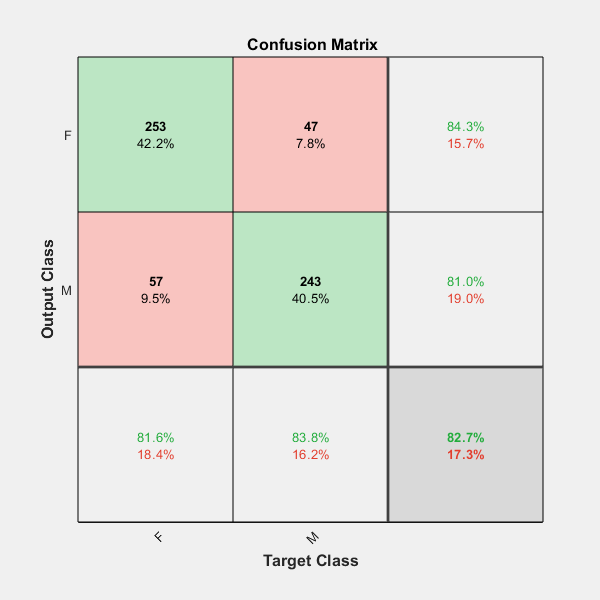

confMat = bsxfun(@rdivide,confMat,sum(confMat,2));

recall = zeros(2,1);
precision = zeros(2,1);
plotconfusion(YPred, YValidation)

for i =1:size(confMat,1)
    recall(i)=confMat(i,i)/sum(confMat(i,:));
end
recall(isnan(recall))=[];
% Recall Calculation
Recall=(sum(recall)/size(confMat,1))*100

Recall = 82.7030

for i =1:size(confMat,1)
    precision(i)=confMat(i,i)/sum(confMat(:,i));
end
% Precision Calculation
Precision=(sum(precision)/size(confMat,1))*100

Precision = 82.7186

% F-score Calculation
F_score=(2*Recall*Precision/(Precision+Recall))

F_score = 82.7108